# 第四章 习题MATLAB代码

% 读入图像
I =imread('cameraman.tif');

## 4-1 请编写利用迭代法进行图像分割的MATLAB程序

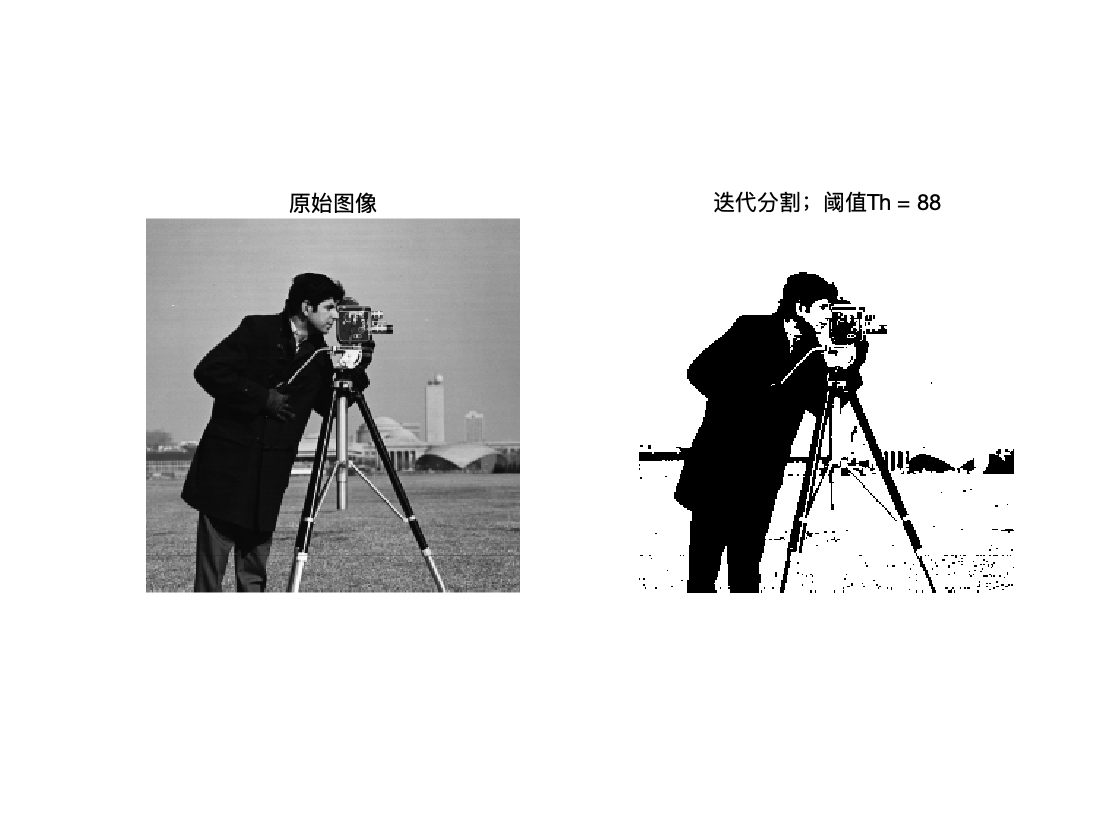

%计算图像的灰度最小值和最大值
tmin=min(I(:));
tmax=max(I(:));
%设定初始阈值
th=(tmin+tmax)/2;
%定义开关变量，用于控制循环次数
ok=true;
%迭代法计算阈值
while ok
    g1= I>=th;
    g2= I<th;
    u1=mean(I(g1));
    u2=mean(I(g2));
    thnew=(u1+u2)/2;
    %设定两次阈值的比较当满足小于1时停止循环
    ok=abs(th-thnew)>=1;
    th=thnew;
end
th=floor(th);
%阈值分割
%J=im2bw(I,th/255);%该用法不被建议
%改为如下用法即可，后面不再说明
J=imbinarize(I,th/255);
%结果显示
figure();
subplot(1,2,1);
imshow(I);title('原始图像');
subplot(1,2,2);
str=['迭代分割；阈值Th = ',num2str(th)];
imshow(J);
title(str);

## `4-2 请编写利用最大类间方差法（Otsu算法）进行图像分割的MATLAB程序`

`MATLAB中提供了计算最大类间方差阈值分割的阈值函数graythresh。level=graythresh(I)根据最大类间方差阈值方差法计算全局阈值，函数返回的阈值的取值范围为[0,1]，输入的图像I可以是uint8、uint16或double型。`

`利用最大类间方差分割法（Otsu算法）进行图像分割的MATLAB代码如下：`

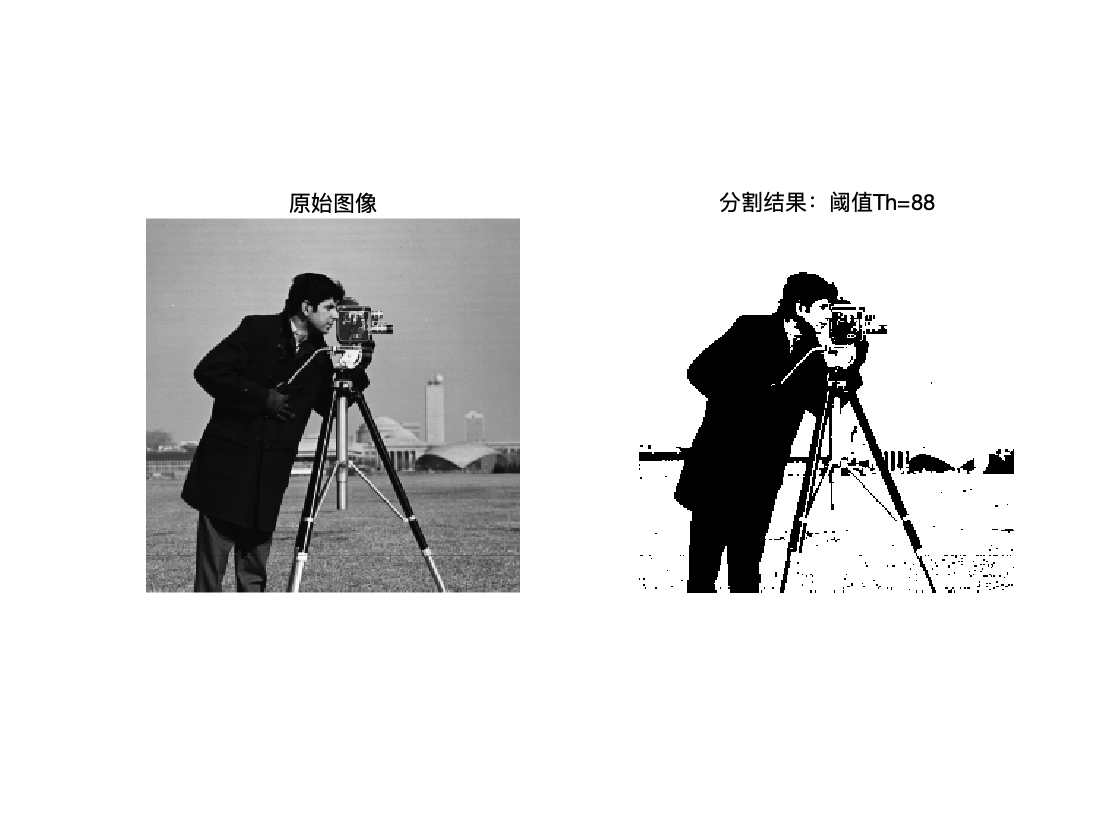

%计算阈值
th=graythresh(I);
%图像分割
J=imbinarize(I,th);
th=255*th;
%结果显示
figure();
subplot(1,2,1);
imshow(I);title('原始图像');
subplot(1,2,2);
imshow(J);title(['分割结果：阈值Th=',num2str(th)]);

## 4-3 边缘检测算子的MATLAB实现

解：MATLAB中提供了边缘检测函数edge，用来完成灰度图像的边缘检测，该函数支持6个不同的边缘检测方法，分别是Sobel算法，Prewitt算法、Roberts算法、LoG算法、Zerocross算法和Canny算法。

## 4-4 边缘检测算子

题目： 请编写MATLAB程序，对一幅数字图像添加高斯噪声，然后分别对原始图像和含噪声的图像用Canny算子进行边缘检测，测试Canny算子对噪声的敏感程度。

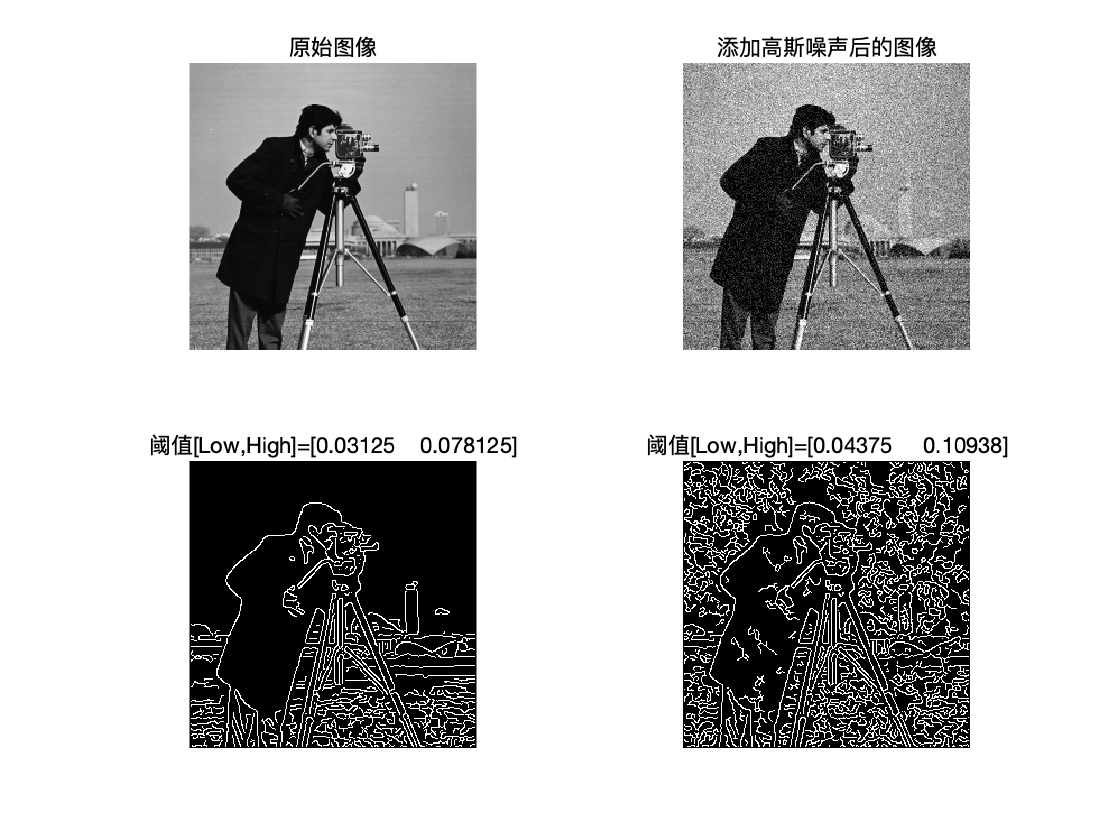

%对图像添加高斯噪声
IN=imnoise(I,'gaussian');
%边缘检测
[BW1,T1] = edge(I,'canny');
[BW2,T2] = edge(IN,'canny');
%结果显示
figure();
subplot(2,2,1);
imshow(I);title('原始图像');
subplot(2,2,2);
imshow(IN);title('添加高斯噪声后的图像');
subplot(2,2,3);
imshow(BW1);title(['阈值[Low,High]=[',num2str(T1),']'])
subplot(2,2,4);
imshow(BW2);title(['阈值[Low,High]=[',num2str(T2),']'])

## 4-5 区域生长法

题目：请编写使用区域生长法进行图像分割的MATLAB程序

解：首先编写区域生长所需的子函数，新建一个m文件，代码见“regiongrow.m”文件，然后编写区域生长的主程序如下：

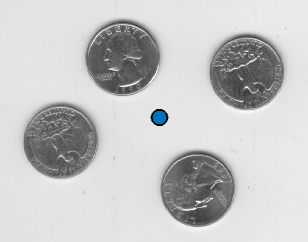

%通过点击选中生长的起始点
Io=imread('eight.tif');
I=double(Io);
figure();
imshow(Io,'Border','tight');
roi = drawpoint();

x1=roi.Position(1);
x2=roi.Position(2);
x1=round(x1);
y1=round(y1);
seed=[x1,y1];

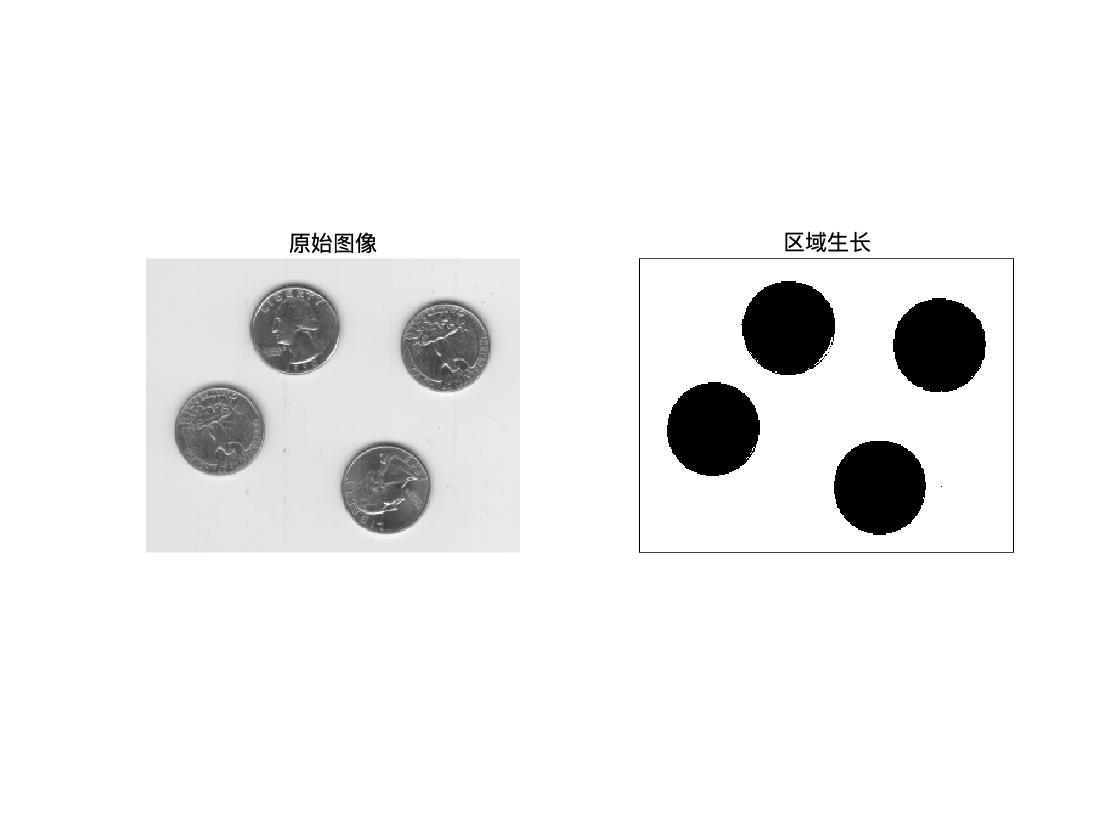

%设定阈值
th_mean=40;
Yout=regiongrow(I,seed,th_mean);
figure();
subplot(1,2,1);
imshow(Io);
title('原始图像');
subplot(1,2,2);
imshow(Yout);
title('区域生长')